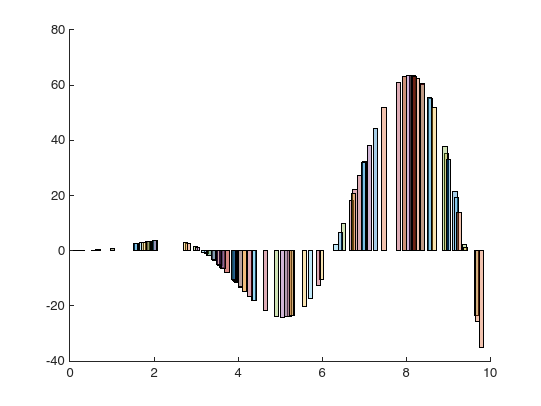

clear
hold on

startX = 0;
endX = 10;

n = 100;

V = rand(1, n) * (endX - startX) + startX;
F = f(V);

h = (endX - startX)/n;

for i = 1:n
    plot(polyshape([V(i)-h/2, V(i)-h/2, V(i)+h/2, V(i)+h/2], [0, F(i), F(i), 0]))
end

function f = f(X)
    f = X.^2 .* sin(X);
end